robot = importrobot('iiwa14.urdf', DataFormat='column')

robot =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'iiwa_link_0'  'iiwa_link_1'  'iiwa_link_2'  'iiwa_link_3'  'iiwa_link_4'  'iiwa_link_5'  'iiwa_link_6'  'iiwa_link_7'  'iiwa_link_ee'  'iiwa_link_ee_kuka'}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'column'


q = randomConfiguration(robot)

q =    -2.4596
   -0.9949
    1.7863
   -1.9720
    2.5449
    0.9648
   -0.0696


%q = robot.homeConfiguration

tf_S = getTransform(robot, q,'iiwa_link_2');
tf_E = getTransform(robot, q,'iiwa_link_4');
tf_W = getTransform(robot, q,'iiwa_link_6');
S = tform2trvec(tf_S)'

S =          0
         0
    0.3600


E = tform2trvec(tf_E)'

E =     0.2735
    0.2220
    0.5887


W = tform2trvec(tf_W)'

W =     0.4318
   -0.1128
    0.4376



tf_EE = getTransform(robot, q,'iiwa_link_ee_kuka');
T = tform2trvec(tf_EE)'

T =     0.5514
   -0.1249
    0.3998


R = tform2rotm(tf_EE)

R =     0.1574    0.2733    0.9490
    0.9697   -0.2246   -0.0962
    0.1869    0.9353   -0.3003



% SEW_type = "Conventional"
% psi = conv_sew(S, E, W, [0;0;1])

SEW_type = "Stereographic"

SEW_type = "Stereographic"

psi = stereo_sew(S, E, W, [0;0;-1], [1;0;0])

psi = 1.9041


GC = [-1 -1 -1];
GC([q(2) q(4) q(6)] >= 0) = 1

GC =     -1    -1     1


jacobian = geometricJacobian(robot,q,'iiwa_link_ee_kuka')

jacobian =     0.0000    0.6303    0.6511   -0.2782    0.3958    0.2616    0.9490
   -0.0000   -0.7763    0.5287   -0.5013   -0.8370   -0.2915   -0.0962
    1.0000    0.0000    0.5446    0.8193   -0.3777    0.9201   -0.3003
    0.1249   -0.0309    0.0890    0.3790    0.0271    0.0222   -0.0000
    0.5514   -0.0251    0.2744    0.1751   -0.0302    0.1199   -0.0000
    0.0000    0.3493   -0.3728    0.2358    0.0953    0.0317   -0.0000



robot.Bodies{5}.Joint

ans =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'iiwa_joint_4'
                 JointAxis: [0 0 1]
            PositionLimits: [-2.0944 2.0944]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


constraintJointBounds(robot).Bounds

ans =    -2.9671    2.9671
   -2.0944    2.0944
   -2.9671    2.9671
   -2.0944    2.0944
   -2.9671    2.9671
   -2.0944    2.0944
   -3.0543    3.0543



kin.p_W_EE = [0; 0; 0.126];
kin.S = [0; 0; 0.36];
kin.d_S_E = 0.42;
kin.d_E_W = 0.4;

qq = anthro_inv_kin(R, T, SEW_type, psi, GC, kin);

show(robot, q,'Visuals','off')

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


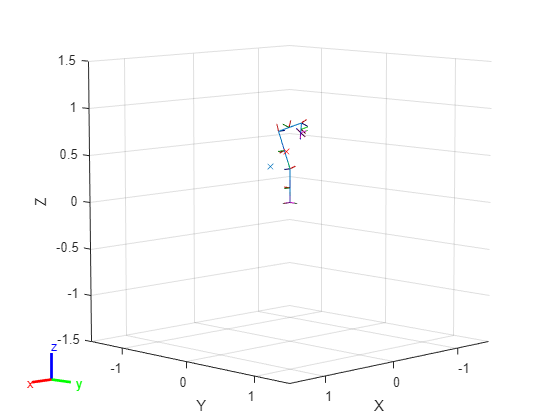

hold on
plot3(debug.C(1),debug.C(2),debug.C(3), 'x')
plot3(debug.E(1),debug.E(2),debug.E(3), 'rx')
hold off


[q qq]

ans =    -1.5436   -1.5436
    0.4091    0.4091
   -0.1222   -0.1222
    1.6694    1.6694
    2.5796    2.5796
    1.3316    1.3316
    1.2762    1.2762
